## Benchmarking test

Implement data and then fit a statistical model to it. Then evaluate the optimum of this model using each optimisation algorithm as a benchmarking test to compare to the real results

% Open data

data = load("Results\Copy_of_cmtmdHPLC007\Copy_of_cmtmdHPLC007.mat")

data = struct with fields:
    data: {7×2 cell}



data = data.data;

conditions = data{2,2};
results = data{3,2};

variedConds = [conditions.GradTime, conditions.InitalOM, conditions.Temp, conditions.IsoHoldTime];
x1 = variedConds(:,1);
x2 = variedConds(:,2);
x3 = variedConds(:,3);
x4 = variedConds(:,4);

peakNumb = -log(abs(cell2mat(results.Maximisepeaknumber))+1);
critRes = -log(abs(cell2mat(results.RsCrit2)-3));
methTime = log(cell2mat(results.Minimisemethodtime));

LB = [1 5 25 0];
UB = [5 95 60 10];

mdlpeakNumb = fitlm([x1 x2 x3 x4], peakNumb, ['y ~ 1 + x1 + x2 + x3 + x4 + x1*x2 + x1*x3 + x1*x4 + x2*x3 + x2*x4 + x3*x4 + x1*x2*x3 + x1*x2*x4 + x1*x3*x4 + x2*x3*x4 + x1*x2*x3*x4'], )

mdlpeakNumb = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x2*x3 + x1*x4 + x2*x4 + x3*x4 + x1:x2:x3 + x1:x2:x4 + x1:x3:x4 + x2:x3:x4 + x1:x2:x3:x4

Estimated Coefficients:
                    Estimate          SE         tStat      pValue 
                   ___________    __________    ________    _______

    (Intercept)        -1.9338        2.9561    -0.65418    0.52935
    x1                -0.36831       0.80061    -0.46004     0.6564
    x2                0.076345      0.082414     0.92636    0.37843
    x3               0.0010204       0.06373    0.016012    0.98757
    x4                -0.78494       0.91599    -0.85694    0.41372
    x1:x2           -0.0068612      0.025757    -0.26638    0.79595
    x1:x3           

mdlcritRes = fitlm([x1 x2 x3 x4], critRes, ['y ~ 1 + x1 + x2 + x3 + x4 + x1*x2 + x1*x3 + x1*x4 + x2*x3 + x2*x4 + x3*x4 + x1*x2*x3 + x1*x2*x4 + x1*x3*x4 + x2*x3*x4 + x1*x2*x3*x4'])

mdlcritRes = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x2*x3 + x1*x4 + x2*x4 + x3*x4 + x1:x2:x3 + x1:x2:x4 + x1:x3:x4 + x2:x3:x4 + x1:x2:x3:x4

Estimated Coefficients:
                    Estimate         SE          tStat      pValue 
                   __________    __________    _________    _______

    (Intercept)       -7.5218        8.9045     -0.84472    0.42016
    x1                 1.9197        2.4116      0.79601    0.44652
    x2                0.12652       0.24825      0.50966    0.62255
    x3                0.14915       0.19197      0.77693    0.45713
    x4               -0.60267        2.7592     -0.21842    0.83197
    x1:x2           -0.049361      0.077588     -0.63619    0.54049
    x1:x3           -

mdlmethTime = fitlm([x1 x2 x3 x4], methTime, ['y ~ 1 + x1 + x2 + x3 + x4 + x1*x2 + x1*x3 + x1*x4 + x2*x3 + x2*x4 + x3*x4 + x1*x2*x3 + x1*x2*x4 + x1*x3*x4 + x2*x3*x4 + x1*x2*x3*x4'])

mdlmethTime = Linear regression model:
    y ~ 1 + x1*x2 + x1*x3 + x2*x3 + x1*x4 + x2*x4 + x3*x4 + x1:x2:x3 + x1:x2:x4 + x1:x3:x4 + x2:x3:x4 + x1:x2:x3:x4

Estimated Coefficients:
                    Estimate         SE          tStat        pValue 
                   ___________    _________    __________    ________

    (Intercept)        -15.872       12.274       -1.2932     0.22816
    x1                  4.8985       3.3242        1.4736     0.17469
    x2                 0.64134      0.34219        1.8742    0.093663
    x3                 0.34188      0.26461         1.292     0.22854
    x4                  1.3527       3.8033       0.35568     0.73027
    x1:x2             -0.18785      0.10695       -1.7565     0.11289
    x1:x3    



% mdlpeakNumb = fitlm([x1 x2 x3], peakNumb, "quadratic")
% mdlcritRes = fitlm([x1 x2 x3], critRes, "quadratic")
% mdlmethTime = fitlm([x1 x2 x3], methTime, "quadratic")

initConds = variedConds(1:25, :);
initResults = [peakNumb(1:25) critRes(1:25) methTime(1:25)];

options = TSEMO_options()

options = struct with fields:
               maxeval: 25
                    GP: [1×3 struct]
                   pop: 100
            Generation: 100
    NoOfBachSequential: 1


[Xpareto,Ypareto,X,Y,XParetoGP,YParetoGP,YParetoGPstd,hypf] = TSEMO_V4(@(x) evalCond(x, mdlpeakNumb, mdlcritRes,mdlmethTime), initConds, initResults, LB, UB, options)

 Iteration     HypImp    Time(s) 
         1      19.94       6.51 
         2      17.04       5.51 
         3      4.249       6.19 
         4      7.991       6.07 
         5      11.71       5.71 
         6      7.825       5.98 
         7      11.06       5.62 
         8      9.614       6.18 
         9      9.517       6.69 
        10      2.746       6.78 
        11      5.866       6.36 
        12       5.89       6.12 
        13      5.451       5.83 
        14      4.696       5.84 
        15      9.017       5.91 
        16      10.36       6.02 
        17      13.07       6.07 
        18      4.348       5.94 
        19      3.212       5.93 
        20      3.847       5.86 
        21      2.573       5.94 
        22      2.996       6.07 
        23      2.529       6.17 
        24      1.575       6.05 
        25      1.108       5.97 


Xpareto =     1.3360    5.5677   26.5960    8.7154
    1.0000    5.1738   26.5235    6.1147
    1.1452    5.7666   25.0000    3.8879
    1.1988    8.4088   25.1976    2.7664
    1.1832    5.9079   25.9408    5.0204
    1.0690    7.7908   25.3418    5.5678
    1.2511    7.2956   25.0000    8.0553
    1.4600    5.0000   25.3717   10.0000
    1.0395    5.0000   25.4772    5.9154


Ypareto =    -4.0100   -4.4353    3.1688
   -3.5921   -4.1226    1.4024
   -2.9875   -3.5935   -0.5315
   -2.5684   -3.1151   -0.9474
   -3.2254   -3.7218    0.5046
   -3.3545   -3.9192    0.8206
   -3.9443   -4.4518    2.3864
   -4.3263   -4.8945    3.6297
   -3.5900   -4.2066    1.0014


X =     2.0989   86.0872   33.9642    4.6751
    1.7120   50.3842   49.4609    3.4782
    2.9057   64.9686   55.6792    8.0481
    1.0759   75.6009   36.5256    6.3310
    3.9190   46.2463   40.0704    2.5269
    4.2486    9.0097   59.0721    0.3506
    3.5156   22.7322   30.8570    1.3344
    2.3356   33.1996   45.6737    5.7699
    3.2242   23.9503   28.3544    9.1951
    4.7749   81.5253   50.3425    7.4972


Y =          0         0    2.7106
   -1.3863   -1.7184    0.6333
   -0.6931   -1.8236   -0.2849
   -0.6931   -0.9705   -0.5574
   -1.3863   -1.9476    1.0841
   -1.9459   -0.7496    1.3232
   -1.9459   -1.1417    1.4469
   -1.6094   -1.9838    2.0086
   -1.9459   -0.9578    2.4749
         0         0    2.7106


XParetoGP =     1.4341    5.0000   25.3355   10.0000
    1.0000    5.1662   25.3355   10.0000
    1.4414    5.0000   25.0000    9.7212
    1.0000    6.7321   25.0000    0.9355
    1.0000    6.7321   25.0000    0.6905
    1.2536    5.0000   25.0000    0.9355
    1.0064    5.0000   25.0000    7.6732
    1.3509    5.0000   25.0000    7.2152
    1.4435    5.0000   25.0081   10.0000
    1.0000    5.0000   25.0000    3.2407


YParetoGP =    -4.3565   -4.9240    3.6104
   -4.1709   -4.9920    3.2478
   -4.4593   -4.8628    3.3961
   -2.7227   -3.3012   -1.4342
   -2.6920   -3.4190   -1.2981
   -2.9285   -3.2568   -1.1353
   -4.0167   -4.6272    2.1319
   -3.9857   -4.4571    2.0075
   -4.4056   -4.9194    3.4892
   -3.0309   -3.5611   -0.8712


YParetoGPstd =     0.0288    0.1247    0.1862
    0.1217    0.3300    0.5192
    0.0875    0.2412    0.3390
    0.1561    0.4197    0.6111
    0.1560    0.4374    0.6659
    0.1711    0.4355    0.6111
    0.1094    0.3217    0.4445
    0.1123    0.3156    0.4902
    0.0451    0.1521    0.2277
    0.0958    0.2525    0.4078


hypf =    25.4321   12.1234    5.9713
  266.6687   93.6629   93.5899
  319.0190   66.1827   57.3459
   96.7230   57.2418   17.9905
    1.2209    1.7846    1.7072
    0.0024    0.0036    0.0031


Data analyis

%Copy of Y data

copyY = Y;

peakNumbNew = round(exp(-copyY(:,1))-1,0)

peakNumbNew =      0
     3
     1
     1
     3
     6
     6
     4
     6
     0


critResNew = exp(-copyY(:,2))-3

critResNew =    -2.0000
    2.5757
    3.1944
   -0.3608
    4.0120
   -0.8837
    0.1321
    4.2703
   -0.3941
   -2.0000


methTimeNew = exp(copyY(:,3))

methTimeNew =    15.0379
    1.8837
    0.7521
    0.5727
    2.9567
    3.7556
    4.2500
    7.4532
   11.8810
   15.0379


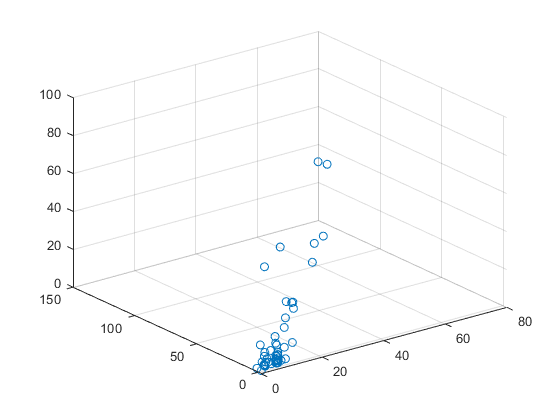


dataNew = [peakNumbNew critResNew methTimeNew];

scatter3(peakNumbNew, critResNew,methTimeNew)


dataNewer = dataNew;
% Isolate data where number of peaks is equal to 6
dataNewer(peakNumbNew ~= 6,:) = []

dataNewer =     6.0000   -0.8837    3.7556
    6.0000    0.1321    4.2500
    6.0000   -0.3941   11.8810
    6.0000   -1.1613    7.1485
    6.0000    0.3074    6.2242
    6.0000    0.2826    2.2776
    6.0000    0.5827    3.3863
    6.0000    0.4435   12.5829
    6.0000   -1.3829    2.7545
    6.0000   -0.9745    2.9247


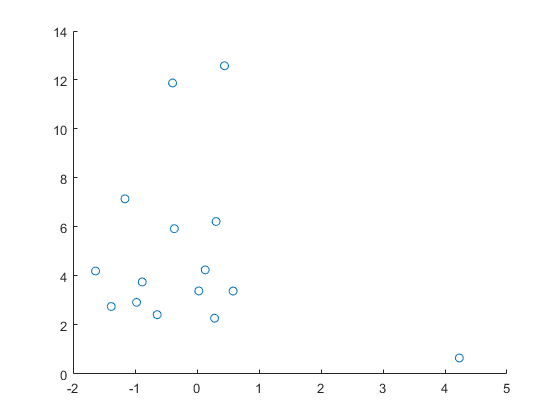


scatter(dataNewer(:,2),dataNewer(:,3))

function resp = evalCond(X, mdlpeakNumb, mdlcritRes,mdlmethTime)
    peakNumbResult = predict(mdlpeakNumb, X);
    critResResult = predict(mdlcritRes, X);
    methTimeResult = predict(mdlmethTime, X);
    
    resp = [peakNumbResult critResResult methTimeResult];
end
